# Option Pricing Using Monte Carlo Method

## Parameter for options and underlying asset

r = 0.02;       %risk-free rate
S0 = 100;       %current price of the underlying stock
sig = 0.25;     %volatility of stock
K = 105;        %strike price
steps = 8;      %number of step to compute (2 months x 4 week/month)
n_paths = 1000;  %number of paths
T = 8/52;       %time to maturity in years
dt = T/steps;   %simulation unit time in years

## Simulating stock price paths

%fix the seed of random number generater for repeatability
rng(1);         

%each column of S is a single path
%each row corrosponds to a single time step 
S = S0*[ones(1,n_paths); ...
            cumprod(exp(r*dt - 0.5*sig*sig*dt +sig*sqrt(dt)*randn(steps,n_paths)),1)]

S =   100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
   97.7539   99.2983   93.3929   93.7182  101.5549  102.0917  103.2409  101.4654  100.1989   95.8559   97.8398  101.4900  100.0414  102.2828  102.3063  101.0750  102.4595   97.2671   96.5289  101.9015   98.3548  100.3446  101.6015   97.9660  101.6473  100.3142   95.2788   93.9211   99.5839   99.4757   98.7234  100.7032  100.7041  101.3789  107.3667  100.3374   98.3600   96.3416   98.2508   99.4489  100.2536   98.3430  102.0675   98.2247   96.8115   94.8688   95.1664   99.6796  102.2143  101

#### Visulize the paths

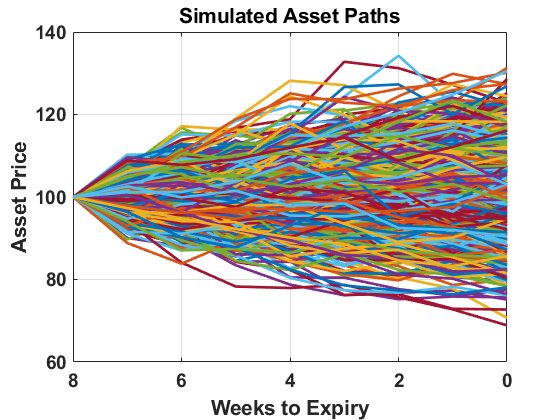

time = steps:-1:0;
plot(time,S,'Linewidth',2);
set(gca,'XDir','Reverse','FontWeight','bold','Fontsize',14);
xlabel('Weeks to Expiry','FontWeight','bold','Fontsize',14);
ylabel('Asset Price','FontWeight','bold','Fontsize',14);
title('Simulated Asset Paths','FontWeight','bold','Fontsize',24);
grid on

set(gcf,'Color','w'); 

## Asian Call price

Asian_call_payoffs = (mean(S) - K).*((mean(S) - K) > 0);
Asian_call_price = exp(-r*T)*mean(Asian_call_payoffs)

Asian_call_price = 0.6768

stderr=std(exp(-r*T)*Asian_call_payoffs)/sqrt(n_paths);
CI_Asian_call_price = [Asian_call_price - 1.96*stderr, Asian_call_price + 1.96*stderr]

CI_Asian_call_price =     0.5645    0.7891


## Asian Put price

Asian_put_payoffs = (K - mean(S)).*((K - mean(S)) > 0);
Asian_put_price = exp(-r*T)*mean(Asian_put_payoffs)

Asian_put_price = 5.3789

stderr=std(exp(-r*T)*Asian_put_payoffs)/sqrt(n_paths);
CI_Asian_put_price = [Asian_put_price - 1.96*stderr, Asian_put_price + 1.96*stderr]

CI_Asian_put_price =     5.0931    5.6647


## Lookback Call price

lb_call_payoffs = (max(S) - K).*((max(S) - K) > 0);
lb_call_price = exp(-r*T)*mean(lb_call_payoffs)

lb_call_price = 3.2893

stderr=std(exp(-r*T)*lb_call_payoffs)/sqrt(n_paths);
CI_lb_call_price = [lb_call_price - 1.96*stderr, lb_call_price + 1.96*stderr]

CI_lb_call_price =     2.9701    3.6085


## Lookback Put price

lb_put_payoffs = (K - min(S)).*((K - min(S)) > 0);  
lb_put_price = exp(-r*T)*mean(lb_put_payoffs)

lb_put_price = 10.7338

stderr=std(exp(-r*T)*lb_put_payoffs)/sqrt(n_paths);
CI_lb_put_price = [lb_put_price - 1.96*stderr, lb_put_price + 1.96*stderr]

CI_lb_put_price =    10.3881   11.0795


## Floating Lookback Call price

flb_call_payoffs = (S(end,:) - min(S)).*((S(end,:) - min(S)) > 0); 
flb_call_price = exp(-r*T)*mean(flb_call_payoffs)

flb_call_price = 5.9949

stderr=std(exp(-r*T)*flb_call_payoffs)/sqrt(n_paths);
CI_flb_call_price = [flb_call_price - 1.96*stderr, flb_call_price + 1.96*stderr]

CI_flb_call_price =     5.6077    6.3822


## Floating Lookback Put price

flb_put_payoffs = (max(S) - S(end,:)).*((max(S) - S(end,:)) > 0);
flb_put_price = exp(-r*T)*mean(flb_put_payoffs)

flb_put_price = 6.2670

stderr=std(exp(-r*T)*flb_put_payoffs)/sqrt(n_paths);
CI_flb_put_price = [flb_put_price - 1.96*stderr, flb_put_price + 1.96*stderr]

CI_flb_put_price =     5.9141    6.6200


## American Put price

#### Least-Squares Monte Carlo (LSM) method proposed by Longstaff and Schwartz (2001) 

%payoff matrix (payoff from exercising at each time step for each path)
h = (K-S).*((K-S) > 0)

h =     5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000
    7.2461    5.7017   11.6071   11.2818    3.4451    2.9083    1.7591    3.5346    4.8011    9.1441    7.1602    3.5100    4.9586    2.7172    2.6937    3.9250    2.5405    7.7329    8.4711    3.0985    6.6452    4.6554    3.3985    7.0340    3.3527    4.6858    9.7212   11.0789    5.4161    5.5243    6.2766    4.2968    4.2959    3.6211         0    4.6626    6.6400    8.6584    6.7492    5.5511    4.7464    6.6570    2.9325    6.7753    8.1885   10.1312    9.8336    5.3204    2.7857    3


% Value matrix (value/price of option at each time step for each path)
v = zeros(steps+1, n_paths);
%value of option at maturity (exercised at maturity)
v(end,:) = h(end,:)

v =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

#### Compare immediate exercise value with continuation value obtained using condition expectation function (polynominal regression) and update value of option to payoff from exercising at given time step where it is optimal to exercise. 

% repeat recusively upto time step 1 
for j = steps:-1:2
    
    %Following steps until the next blank line are to find Ci
    %find paths where option is in-the-money at timestep j-1
    I = find(h(j,:));
    %obtain stock price at timestep j-1 where option is in-the-money
    X = S(j,I);
    %discount option value at timestep j to j-1 where option is in-the-money 
    Y = v(j+1,I)*exp(-r*dt);
    %obtain condition expectation function (polynomial of degree 2)
    reg = polyfit(X, Y, 2);
    %find continuation value
    c = polyval(reg, X);
    
    %assign option value at timestep j-1
    v(j,:) = v(j+1,:)*exp(-r*dt);
    
    %find paths where it is optimal to exercise at timestep j-1
    II = nonzeros(I.*(h(j,I) > c))';
    %upadte the option values to payoffs from exercising at timestep j-1
    %where it is optimal
    v(j,II) =  h(j,II);
    
end

#### Discount option value for each path from time step 1 to time step 0. 

v(1,:) = v(2,:)*exp(-r*dt);
v

v =    15.4047    6.4306   15.6374   14.6438         0   14.1185   18.5778   13.5631    5.6011         0    8.4699   10.1466         0         0   15.0796    6.4797         0   14.4119   10.1506    3.2214    4.9598    7.9948    5.3352    6.9261         0         0   11.1837         0   10.8829         0         0         0    7.7731         0         0   11.0985    0.7546    6.2277   17.4325   13.6720   10.6169         0         0    2.9900         0   13.8070    7.5628   18.2505         0   17.9812
   15.4107    6.4330   15.6435   14.6494         0   14.1240   18.5849   13.5683    5.6032         0    8.4732   10.1505         0         0   15.0854    6.4822         0   14.4174   10.1545    3.2226    4.9617    7.9978    5.3373    6.9287         0         0   11.1880         0   10.8871         0         0         0    7.7761         0         0   11.1028    0.7549    6.2301   17.4392   13.6773   10.6210         0         0    2.9911         0   13.8123    7.5657   18.2575         0   17

#### Take average of option values to find the price

%American put option price at time 0.
American_put_price = mean(v(1,:))

American_put_price = 6.9836

stderr=std(v(1,:))/sqrt(n_paths);
CI_American_put_price = [American_put_price - 1.96*stderr, American_put_price + 1.96*stderr]

CI_American_put_price =     6.5458    7.4214
